# Part3: OFDM & Frequency Selective Channel

# Transmitter

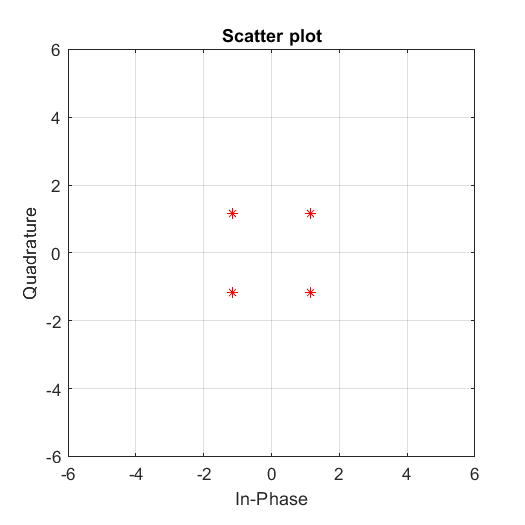

RepCode_En = 0;
MUL = 0;
if(RepCode_En == 0)
    N_Bits = 256*(10^MUL);
else
    N_Bits = 252*(10^MUL);
end
BitStream_Data = randi([0 1],[1, N_Bits]);
Eb = 4;
Modulation_Order = [4 16,4 16];
m = [8 16 8 16];
N_SubCarriers = 64;

SymbolStream = {};
OFDM_SymbolStream = {};
Constellation = {};

for i = 1:4
    if (i > 2)
        RepCode_En(i) = 1;
        BitStream = repelem(BitStream_Data,3);
        Eb = Eb/3;
    else 
        RepCode_En(i) = 0;
        BitStream = BitStream_Data;   
    end
    if(RepCode_En == 1)
        BitStream = PADDING(BitStream, Modulation_Order(i));
    end
    BitStream = interleaver(BitStream,m(i));
    
    [SymbolStream{i}, Constellation{i}] = Modulate(BitStream,Eb,Modulation_Order(i));
    OFDM_SymbolStream{i} = reshape(SymbolStream{i},length(SymbolStream{i})/N_SubCarriers,N_SubCarriers);
end

scatterplot(Constellation{3},1,0,'r*');
grid on
axis([-6 6 -6 6]);

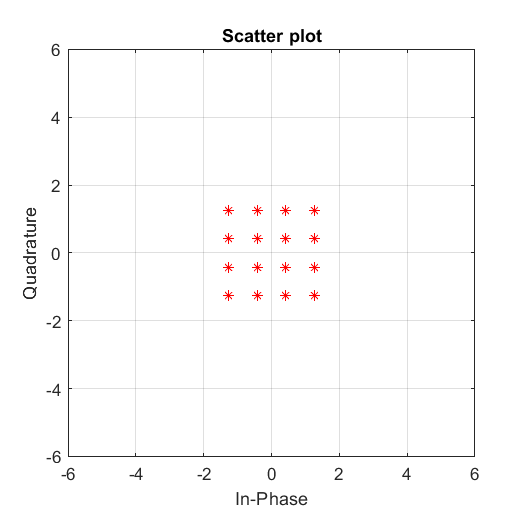

scatterplot(Constellation{4},1,0,'r*');
grid on
axis([-6 6 -6 6]);

#  Channel Model

The Channel is modeled by creating multipaths.

Since the channel is not represented by single paths therefore each symbol will be output of the channel will have extra samples equal to Number of Resolvable Paths -1

By Showing its frequency domain we can note that its indeed frequency selective channel.

SNR_dB = -2:10;
No = db2mag(-2*SNR_dB)*4;

N_OFDM_Symbols = {};   H = {};  N = {}; Channel_OUT = {};
for i=1:4
N_OFDM_Symbols{i} = size(OFDM_SymbolStream{i},1);

U_R = 0;       Sigma_R = sqrt(0.5);
U_I = 0;       Sigma_I = sqrt(0.5);
H_R = randn([1 N_SubCarriers])*Sigma_R + U_R;
H_I = randn([1 N_SubCarriers])*Sigma_I + U_I;

H{i} = H_R + H_I*1j;

%Noise power will be determined by the SNR value
%SNR = Eb/No

N_c = randn([1 N_SubCarriers]);
N_s = randn([1 N_SubCarriers]);
N{i} = N_c + N_s*1j;
N{i} = sqrt(No/2)*repmat(N{i},length(SNR_dB),1);
%% Sending the signal through the channel
% Since the channel is represented by delta (One Resorvable Path)
% 
% Then the channel output will be simple multiplication with the channel value, 
% where each symbol will only be scaled by a gain and added phase.
% 
% Then the White Gaussian Noise is added. 

Channel_OUT{i} = OFDM_SymbolStream{i}.*H{i};
Channel_OUT{i} = Channel_OUT{i} + N{i};
end

# Receiver

for i=1:length(Channel_OUT)
    OFDM_REC_Symbol_Stream{i} = Channel_OUT{i}./H{i};
end
for i=1:length(Channel_OUT)
    for j=1:size(OFDM_REC_Symbol_Stream{i},1)
        DEM_Bit_Stream{i}(j,:) = Demap(OFDM_REC_Symbol_Stream{i}(j,:), Constellation{i});
        DEI_Bit_Stream{i}(j,:) = deinterleaver(DEM_Bit_Stream{i}(j,:),m(i));
        if(RepCode_En(i) == 1)
            DEP_Bit_Stream{i}(j,:) = DEPADDING(DEI_Bit_Stream{i}(j,:),Modulation_Order(i));
            DEC_Bit_Stream{i}(j,:) = DECODING(DEP_Bit_Stream{i}(j,:));
            REC_Bit_Stream{i}(j,:) = DEC_Bit_Stream{i}(j,:);
        else
            REC_Bit_Stream{i}(j,:) = DEI_Bit_Stream{i}(j,:);
        end
    end
end

## BER EVALUATION

for i = 1:4
BER{i} = zeros(length(SNR_dB),N_Bits);
for l = 1:length(SNR_dB)
    if (i == 2 || i==4)
        BER{i}(l,:) = xor(REC_Bit_Stream{i}(l,:),BitStream_Data);
    else
        
    end
end

BER{i} = sum(BER{i},2)/N_Bits;
end



## evaluating BER (there is a problem here)

figure
    hold on
    semilogy(SNR_dB, transpose(BER))
    hold off
    title('BER vs SNR')
    xlabel('SNR(db)')
    ylabel('BER')
    ylim([0,0.002])

function [SymbolStream, S] = Modulate(BitStream, Eb, Order)
%This function takes the bit stream and modulate it according
%to modulation order
%Modulation order varies from 2:BPSK 4:QPSK 16:16-QAM
%Eb: Energy per Bit

N_Bits = length(BitStream);

switch (Order)
    case 2
        A = sqrt(Eb);
        SymbolStream = (2*BitStream-1)*A;
        S = 2;
    
    case 4
        A = sqrt(Eb);
        %Creating the constellation:
        %Index represents the mapped bits - 1
        %ex: 00-> index:1 -> (-1-j)*A
        S(1) = - 1 - 1j;
        S(2) = - 1 + 1j;
        S(3) =   1 - 1j;
        S(4) =   1 + 1j;
        S = S*A;
        
        SymbolStream = reshape(BitStream,[2, N_Bits/2])';
        SymbolStream = num2str(SymbolStream);
        SymbolStream = bin2dec(SymbolStream)';
        SymbolStream = S(SymbolStream+1);
        
    case 16
        % Eb = 2.5E -> A = sqrt(E)
        A = sqrt(0.4*Eb);
        %Creating the constellation:
        %Index represents the mapped bits - 1
        %ex: 0000-> index:1 -> (-3-3j)*A
        S(1) = - 3 - 3j;
        S(2) = - 3 - 1j;
        S(3) = - 3 + 3j;
        S(4) = - 3 + 1j;
        S(5) = - 1 - 3j;
        S(6) = - 1 - 1j;
        S(7) = - 1 + 3j;
        S(8) = - 1 + 1j;
        S(9) =   3 - 3j;
       S(10) =   3 - 1j;
       S(11) =   3 + 3j;
       S(12) =   3 + 1j;
       S(13) =   1 - 3j;
       S(14) =   1 - 1j;
       S(15) =   1 + 3j;
       S(16) =   1 + 1j;
        S = S*A;
        
        SymbolStream = reshape(BitStream,[4, N_Bits/4])';
        SymbolStream = num2str(SymbolStream);
        SymbolStream = bin2dec(SymbolStream)';
        SymbolStream = S(SymbolStream+1);
end

end

function [Out_BitStream] = Demap(SymbolStream, S)
%This function takes the Symbol Stream after channel inversion
%And Decodes it according maximum Liklihood decoding
%aka: minimum distance to contellation point,
%since we are using eqiprobable signals
%Decoded symbols are directly converted to bits
%S is an array that carries the constellation points
%The Function then applies  Hard Decision Decoding
%Where its index is the equivalent binary value + 1

N_Symbols = length(SymbolStream);
Order = length(S);

if(S == 2)
    %BPSK case
    SymbolStream = real(SymbolStream);
    Out_BitStream(SymbolStream>0) = 1;
    Out_BitStream(SymbolStream<0) = 0;
else
    SS_mod = repmat(SymbolStream,Order,1);
    Rep_con = transpose(repmat(S,N_Symbols,1));
    Distance = SS_mod - Rep_con;
    Distance = abs(Distance);
    
    [~, Index] = min(Distance);
    %Output Bit stream in decimal
    Out_BitStream = Index-1;
    Out_BitStream = decimalToBinaryVector(Out_BitStream,log2(Order),'MSBFirst')';
    Out_BitStream = reshape(Out_BitStream,1,N_Symbols*log2(Order));
end
end

function data_out = interleaver(data,m)
L = 16; % Number of rows(m) and columns(L)
nb = m*L;  % Size of interleaver
k = 0:nb-1;  % interleaver output indexing vector
i = L*mod(k,m)+floor(k/m);  % intermediate variable
j = (nb/2)*floor(2*i/nb)+mod((i+nb),nb/2); % interleaver input indexing vector
data_out = zeros(1,length(data));
for ii = 1: length(data)/(m*L)
    temp = data((ii-1)*nb+1:ii*nb);
    data_out((ii-1)*nb+1:ii*nb) = temp(j+1);
end
end

function data_out = deinterleaver(data,m)
L = 16; % Number of rows(m) and columns(L)
nb = m*L;  % Size of interleaver
k = 0:nb-1;  % interleaver output indexing vector
i = L*mod(k,m)+floor(k/m);  % intermediate variable
j = (nb/2)*floor(2*i/nb)+mod((i+nb),nb/2); % interleaver input indexing vector
data_out = zeros(1,length(data));
temp = zeros(1,nb);
for ii = 1: length(data)/(m*L)
    temp(j+1) = data((ii-1)*nb+1:ii*nb);
    data_out((ii-1)*nb+1:ii*nb) = temp;
end
end

function Padded_BitStream = PADDING(BitStream, ModulationOrder)

if ModulationOrder == 4
    N_PAD = 2;
    L_BLOCK = 126;
end
if ModulationOrder == 16
    N_PAD = 4;
    L_BLOCK = 252;
end

N_BLOCKS = length(BitStream)/L_BLOCK;

Padded_BitStream = reshape(BitStream, [L_BLOCK, N_BLOCKS])';

Zero_Padding = zeros(N_BLOCKS, N_PAD);

Padded_BitStream = [Padded_BitStream, Zero_Padding];

Padded_BitStream = reshape(Padded_BitStream', [1, N_BLOCKS*(L_BLOCK+N_PAD)]);
end

function DePadded_BitStream = DEPADDING(Padded_BitStream, ModulationOrder)

if ModulationOrder == 4
    N_PAD = 2;
    L_BLOCK = 126;
end
if ModulationOrder == 16
    N_PAD = 4;
    L_BLOCK = 252;
end

N_BLOCKS = length(Padded_BitStream)/(L_BLOCK+N_PAD);

DePadded_BitStream = reshape(Padded_BitStream, [(L_BLOCK+N_PAD), N_BLOCKS])';

DePadded_BitStream = DePadded_BitStream(:, 1:(end-N_PAD) );

DePadded_BitStream = reshape(DePadded_BitStream', [1, N_BLOCKS*L_BLOCK]);
end

function Decoded_Bit_Stream = DECODING(DePadded_BitStream)
        Decoded_Bit_Stream = reshape(DePadded_BitStream,3,[]);
        Decoded_Bit_Stream = mode(Decoded_Bit_Stream);
end
